力矩圖生成器

載入數據及求出其長度

clear;
load MomentChangingLD260k0.5.mat;
dataLength = length(export);
% sortAccordingToMtotalFitRMSE = false;
field="l"

field = "l"

showSlope=true;
markMaxOrMin=true;
plotMg = true

plotMg = logical
   1


objective = [30 60 90 120 150 180 210];
indObjective = find_ind([export(:).l], objective)

indObjective =      1     4     7    10    13    16    19


% indObjective = sort(indObjective)
color=char('#0072BD', '#D95319', '#EDB120', '#7E2F8E', '#77AC30', '#4DBEEE', '#A2142F')

color = 7×7 char array
    '#0072BD'
    '#D95319'
    '#EDB120'
    '#7E2F8E'
    '#77AC30'
    '#4DBEEE'
    '#A2142F'


markerSize = 10;
yupperlim=4

yupperlim = 4

ylowerlim=0

ylowerlim = 0

%  for j= 1:1
%     if sortAccordingToMtotalFitRMSE==true
%         i=export(1).idx(1);
%     else
%         i=j;
%     end

fig1 = figure;

fig1.Position = [0 0 900 600];

if plotMg==1
    plot(export(1).thetad, export(1).Mg, 'k-.', "DisplayName","Mg","LineWidth",2); hold
end

Current plot held


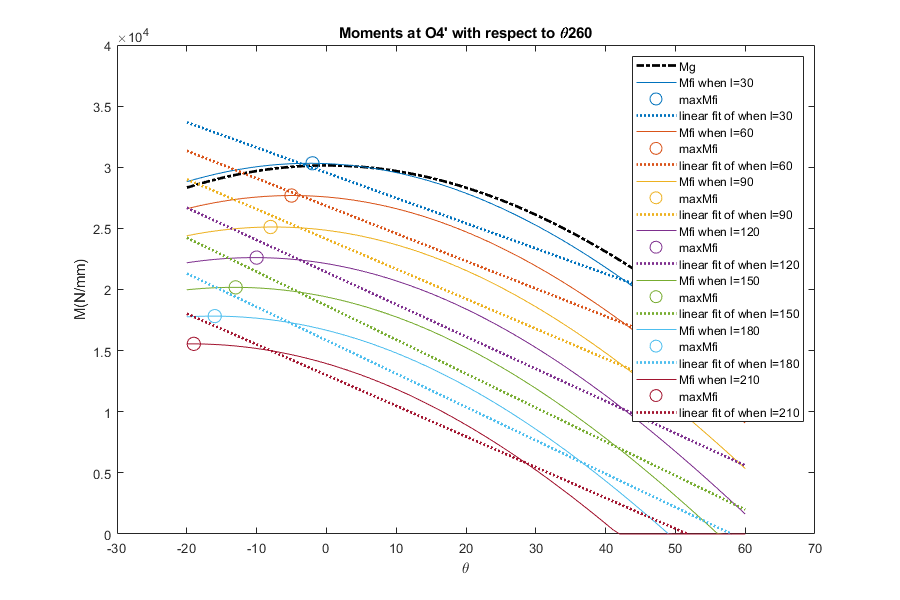


count = 1;
for i = indObjective
    angleCount = length(export(i).thetad);
    
    plot(export(i).thetad, export(i).Mfi, '-'...
        , 'DisplayName',"Mfi when "+field+"="+objective(count)...
        ,"Color",color(count,:)); hold on;
    if markMaxOrMin==1
        if export(i).d >0
            [~,imx]=max(export(i).Mfi(:));
            plot(export(i).thetad(imx), export(i).Mfi(imx),'o'...
                ,'DisplayName', "maxMfi"...
                ,"Color",color(count,:)...
                ,'MarkerSize', markerSize); hold on
        elseif export(i).d <0
                [~,imx]=min(export(i).Mfi(:));
                plot(export(i).thetad(imx), export(i).Mfi(imx),'o'...
                    ,'DisplayName', "minMfi"...
                    ,"Color",color(count,:)...
                    ,'MarkerSize', markerSize); hold on
       end
    end
    if showSlope==1
        p = polyfit(export(i).thetad, export(i).Mfi,1);
        plot(export(i).thetad, polyval(p,export(i).thetad), ':'...
            , "DisplayName","linear fit of when "+field+"="+objective(count)...
            , "LineWidth",2 ...
            ,"Color",color(count,:));
    end
    
    count = count+1;
end
axis([-30 70 ylowerlim*(10^4) yupperlim*(10^4)]);
title("Moments at O4' with respect to \theta" + export(i).d);
xlabel("\theta");
ylabel("M(N/mm)");
legend;
hold off;

function ind = find_ind(range, object)
ind = find(ismember(range, object));
end